We can change the position of the load from 0m to 1m

x=0.8; %Location of Load

Piece of code below calculates and plots the shear and moment for a simply supported Beam! It may look complicated, but it is really simple!

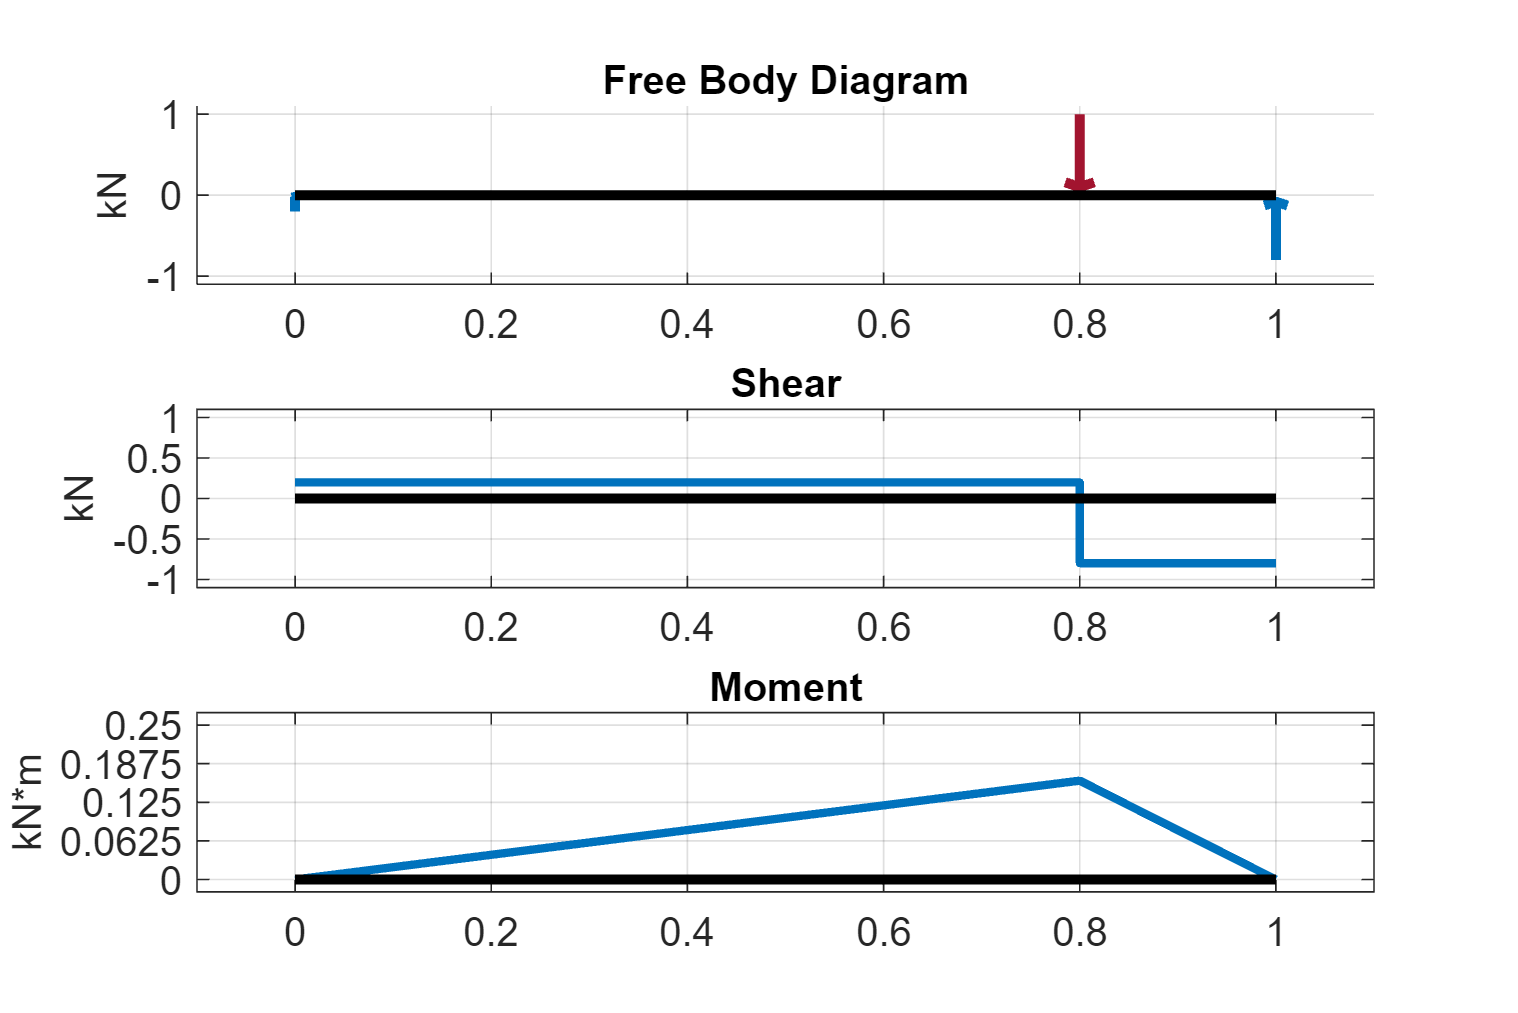

L=1; P=1; %Magnitude of Length and Load (m and kN)
V1=P*(L-x)/L; V2=P-V1; %Shear at left and right support

%Start Plotting
f = figure();
f.WindowState = 'maximized';
figure('Renderer', 'painters', 'Position', [10 10 900 600])

%Plot Free Body Diagram
subplot(3,1,1);
hold on
h=quiver(0,-V1,0,V1,'Color',[0 0.4470 0.7410]);
set(h,'LineWidth',3)
h=quiver(x,P,0,-P,'Color',[0.6350 0.0780 0.1840]);
set(h,'LineWidth',3)
h=quiver(L,-V2,0,V2,'Color',[0 0.4470 0.7410]);
set(h,'LineWidth',3)
title('Free Body Diagram')
plot([0,L],[0,0],'k',LineWidth=3)
ylabel('kN')
xlim([-0.1,1.1])
ylim([-P-0.1,P+0.1])
grid on

%Start Plotting Shear
subplot(3,1,2);
plot([0,x-1e-6,x+1e-6,L],[V1,V1,-V2,-V2],linewidth=2.5)
xlim([-0.1,1.1])
ylim([-P-0.1,P+0.1])
title('Shear')
ylabel('kN')
grid on
set(gca,'ytick',linspace(-1,1,5))
hold on 
plot([0,L],[0,0],'k',LineWidth=3)

%Start Plotting Moment
subplot(3,1,3);
plot([0,x,L],[0,V1*x,0],linewidth=2.5)
xlim([-0.1,1.1])
ylim([0-0.02,P*L/4+0.02])
title('Moment')
ylabel('kN*m')
grid on
set(gca,'ytick',linspace(0,P*L/4,5))
set(findall(gcf,'-property','FontSize'),'FontSize',12)
hold on 
plot([0,L],[0,0],'k',LineWidth=3)